%% === Load correlation vector time series ===
%% === Subject ===
subject= '100610'; 

relative_path = fullfile('..', 'Usedata', 'rfMRI_ts', ...
                         [subject, '_REST1_LR_AAL_corr_vec.txt']);
file = fullfile(pwd, relative_path); 

V = readmatrix(file);  % V: 6670 x 1081
fprintf("Loaded correlation matrix: [%d x %d]\n", size(V,1), size(V,2));

Loaded correlation matrix: [6670 x 1081]


%% === Sliding window to build point clouds ===
win_size = 60;
n_series = size(V, 2);
n_points = n_series - win_size + 1;
D_all = cell(1, n_points);   % to hold 60x60 distance matrices

for t = 1:n_points
    X = V(:, t:t+win_size-1)';                  % (60 x 6670)
    D = squareform(pdist(X, 'euclidean'));      % (60 x 60) Euclidean distance

    % --- Preprocessing ---
    D = double(D);                              % Ensure double
    D(isnan(D) | isinf(D)) = 999;               % Sanitize invalid entries
    D(1:end+1:end) = 0;                          % Diagonal zero
    D = (D + D') / 2;                            % Symmetrize

    D_all{t} = D;
end

%% === Convert cell array to 3D array ===
D_tensor = cat(3, D_all{:});   % (60 x 60 x 1022)

%% === Add PH-STAT to path ===
package_path = fullfile('..', 'ExternalPackages', 'PH-STAT-main');
addpath(package_path);

%% === Test on first point cloud ===
[Wb1, Wd1] = WS_decompose(D_tensor(:,:,1));  % birth-death from t=1

%% === Full topological trajectory embedding ===
[z, c] = WS_embed(D_tensor);  % z.x, z.y: 1022-length trajectory

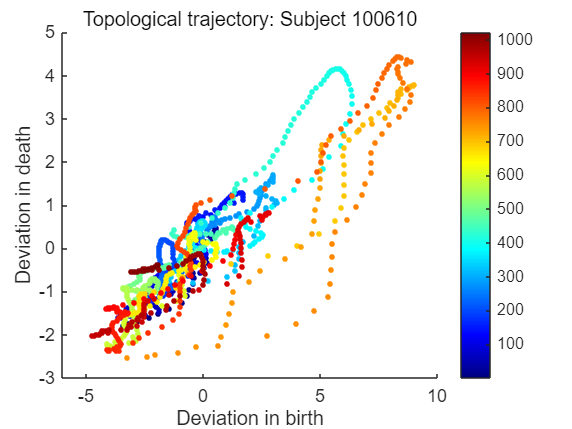

%% === Visualize the result ===
figure;
scatter(z.x, z.y, 10, 1:n_points, 'filled');
colormap(jet); colorbar;
xlabel('Deviation in birth'); ylabel('Deviation in death');
title(sprintf('Topological trajectory: Subject %s', subject));

xlim padded; ylim padded;